# Actividad 3.1: Trayectorias en lazo abierto (Zig Zag)

En esta actividad se implementa el código requerido para generar las siguientes trayectorias a partir de las velocidades angulares y lineales en un plano 2D. En este segundo ejercicio se busca trazar tramos predefinidos, formando una especie de zigzag**.**

%Limpieza de pantalla
clear all
close all
clc

**Se declara el tiempo de ejecución**

tf=9.5;            % Tiempo de simulación en segundos (s) para 8 movimientos
ts=0.1;            % Tiempo de muestreo en segundos (s)
t=0:ts:tf;         % Vector de tiempo
N= length(t);      % Muestras

**Se declaran las condiciones iniciales a tomar en cuenta**

%Inicializamos las variables que se van a emplear
x1= zeros (1, N+1);       % Posición (X) en el centro del eje que une 
% las ruedas en metros (m)
y1= zeros (1, N+1);       % Posición (Y) en el centro del eje que une 
% las ruedas en metros (m)
phi= zeros (1, N+1);      % Orientación del robot en radiaanes (rad)

%Damos valores a nuestro punto inicial de posición y orientación
x1(1)=0;  %Posición inicial eje x
y1(1)=0;  %Posición inicial eje y
phi(1)=0; %Orientación inicial del robot 

**Se declara el punto de control en referencia al robot **

%Inicializamos el punto de control 
hx= zeros (1, N+1);       % Posición en el eje (X) del punto de control en metros (m)
hy= zeros (1, N+1);       % Posición en el eje (Y) del punto de control en metros (m)

%Igualamos el punto de control con las proyecciones X1 y Y1 por su
%coincidencia
hx(1)= x1(1);       % Posición del punto de control en el eje (X) metros (m)
hy(1)= y1(1);       % Posición del punto de control en el eje (Y) metros (m)

**Se declaran las velocidades de referencia**

La lógica para cada trayectoria se define de la siguiente manera, haciendo un total de 8 pasos nuevamente:

`Tramo 1 (v=0 m/s, w=pi/6 rad/s) - Gira 30°`

`Tramo 2 (v=1 m/s, w=0 rad/s) - Avanza 1 metro`

`Tramo 3 (v=0 m/s, w=2/3pi rad/s) - Gira 120°`

`Tramo 4 (v=1 m/s, w=0 rad/s) - Avanza 1 metro`

`Tramo 5 (v=0 m/s, w=-2/3pi rad/s) - Gira -120°`

`Tramo 6 (v=1 m/s, w=0 rad/s) - Avanza 1 metro`

`Tramo 7 (v=1 m/s, w=0 rad/s) - Avanza 1 metro`

`Tramo 8 (v=0 m/s, w=pi/2 rad/s) - Gira 90°`

`Va aumentando el número de muestras (N) para lograr que el robot complete la secuencia de movimientos`

v = [0*ones(1,10) 1*ones(1,10) 0*ones(1,10) 1*ones(1,10) 0*ones(1,10) 1*ones(1,15) 0*ones(1,10) 1*ones(1,21)]; % Velocidad lineal de referencia (m/s)
w = [pi/6*ones(1,10) 0*ones(1,10) 2/3*pi*ones(1,10) 0*ones(1,10) -2/3*pi*ones(1,10) 0*ones(1,15) -pi/2*ones(1,10) 0*ones(1,21)]; % Velocidad angular de referencia (rad/s)

**Se inicia bucle de simulación en el cual se declara el modelo cinemático**

for k=1:N 
    
    %Aplico la integral a la velocidad angular para obtener el angulo 
    %"phi" de la orientación
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
    
    xp1=v(k)*cos(phi(k)); 
    yp1=v(k)*sin(phi(k));
 
    %Aplico la integral a la velocidad lineal para obtener las cordenadas
    %"x1" y "y1" de la posición
    x1(k+1)=x1(k)+ ts*xp1; % Integral numérica (método de Euler)
    y1(k+1)=y1(k)+ ts*yp1; % Integral numérica (método de Euler)

    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

**Ahora se inicia con la simulación virtual en 3D**

Para esta parte se importan los archivos compartidos por el profesor: MobilePlot.m, MobileRobot.m y Uniciclo.mat que se encuentran en la misma carpeta que este código, esto con el fin de poder graficar el entorno en 3D simultáneamente con este programa.

A continuación se muestran los pasos para la visualización:

**a) Configuracion de escena**

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Configurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos 
% sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([135 35]); % Orientacion de la figura
axis([-3 3 -3 3 0 2]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

**b) Graficar robots en la posicion inicial**

scale = 4;
MobileRobot;
H1=MobilePlot(x1(1),y1(1),phi(1),scale);hold on;

**c) Graficar Trayectorias**

H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

**d) Bucle de simulacion de movimiento del robot**

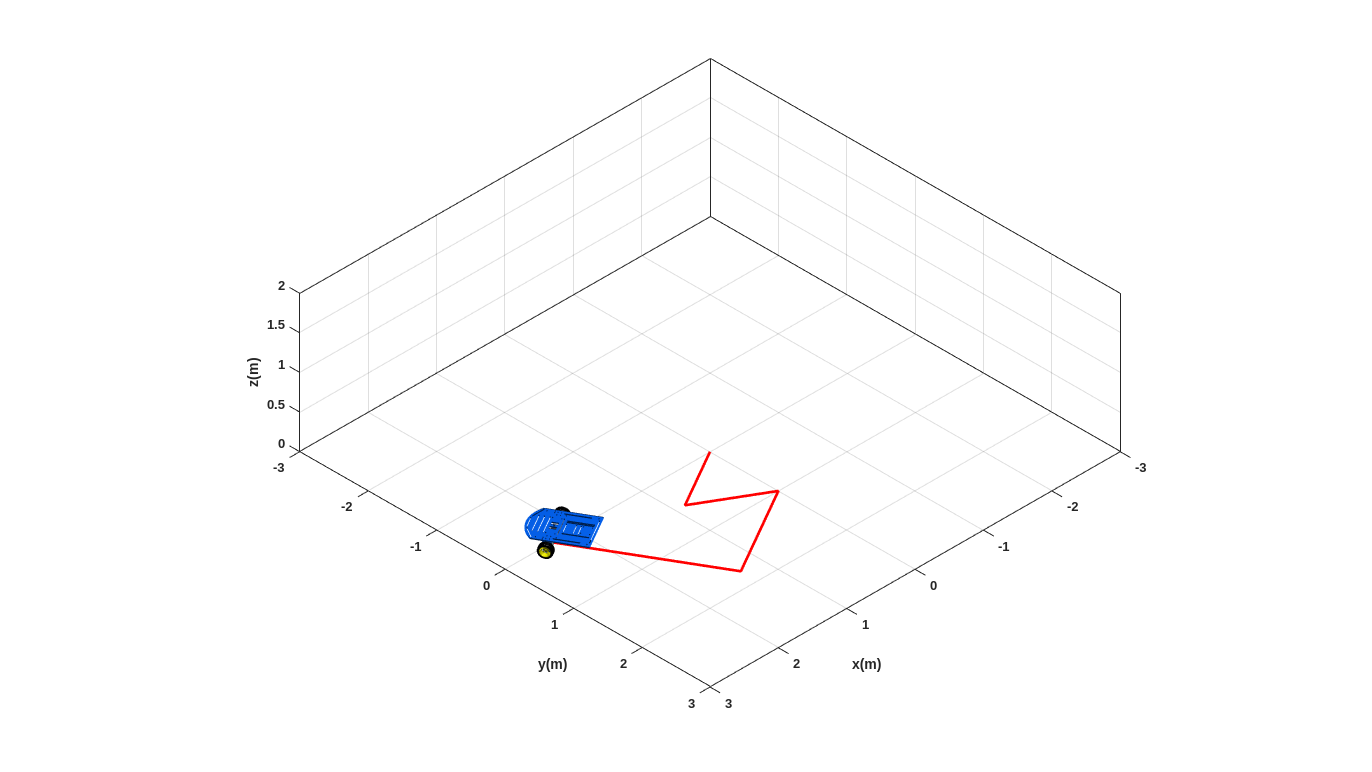

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

Este ejercicio nos ayuda a visualizar como funciona la manipulación de un robot modular declarándole la distancia y el ángulo que debe ejecutar para lograr la trayectoria deseada. Lo cual será muy útil para la realización del reto final.